# Programming and Scripts

[Open live script](matlab:edit physvis_toolbox_programming)

To use PHYSVIS classes, you can write out their full name such as

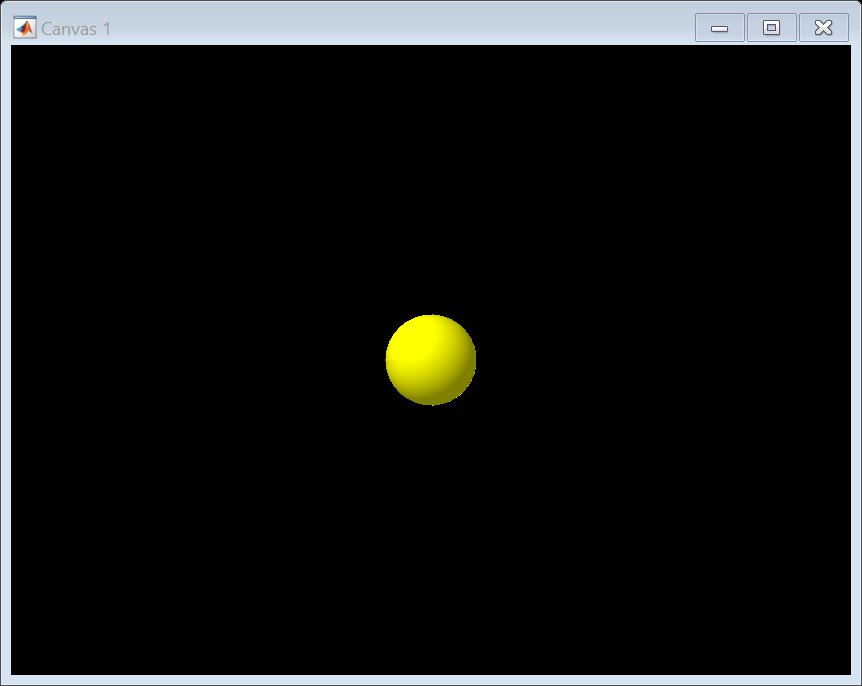

myBall = physvis.Sphere();

or you can start your script with the statement

import physvis.Sphere

and omit the leading `physvis` such as

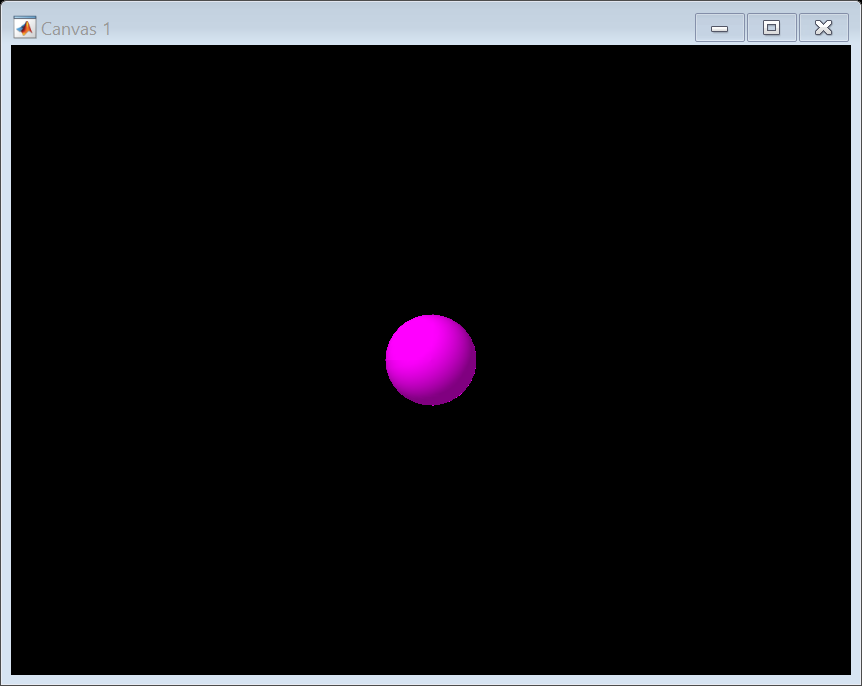

myBall = Sphere();

If you'd like to omit the leading `physvis` for all PHYSVIS classes, instead include the statement

import physvis.*

To clear the current import list, type `clear import` at the MATLAB command prompt. Do not call `clear import` within a function or a script.

To clear the Sphere object from the figure window, type

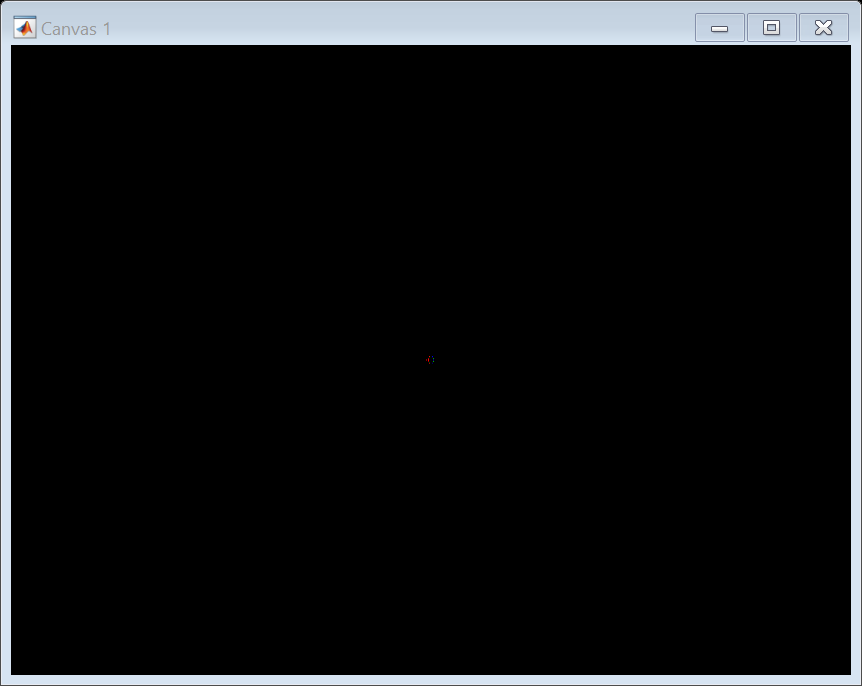

clear myBall

Whenever you write code, it is a good practice to add comments that describe the code. Comments allow others to understand your code, and can refresh your memory when you return to it later. Add comments using the percent (%) symbol.

% Generate random data from a uniform distribution
% and place balls at these locations.
n = 50;            % 50 data points
r = 10*(rand(n,3) - 0.5);

Within a script, you can loop over sections of code and conditionally execute sections using the keywords `for`, `while`, `if`, and `switch`.

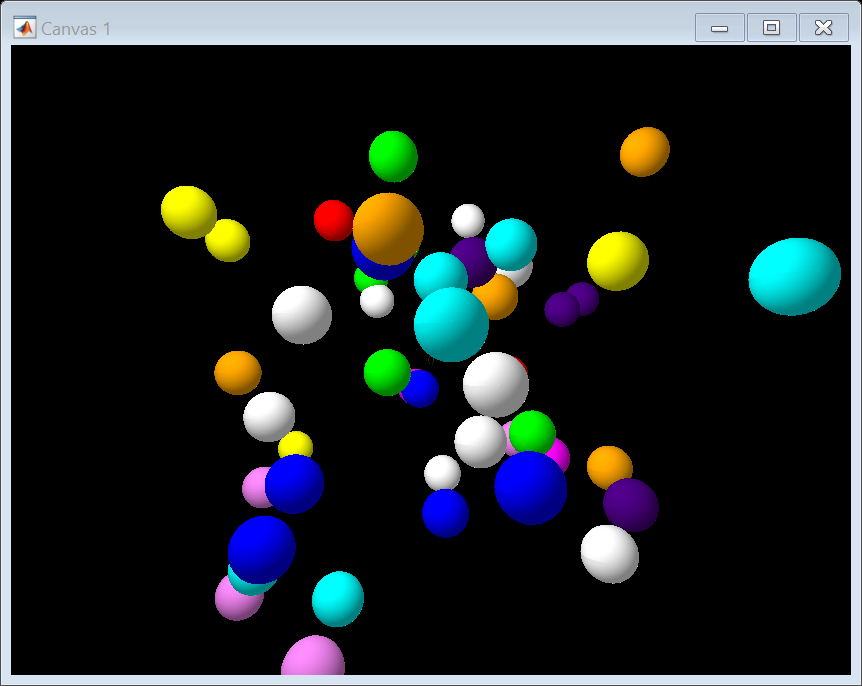

% Allocate memory for n balls
ball(n) = Sphere();
% Place the balls at each r
for k = 1:n
    ball(k) = Sphere('Radius',0.5,'Position',r(k,:));
end

© Copyright 2017 The MathWorks, Inc.